# LEARNING MOTION PATTERNS IN AIS DATA AND DETECTING ANOMALOUS BEHAVIOR

unique(HawaiiAIS2019123120200330.MMSI);

k=find(HawaiiAIS2019123120200330.MMSI==245206000);
dataSubset = HawaiiAIS2019123120200330(k, :);

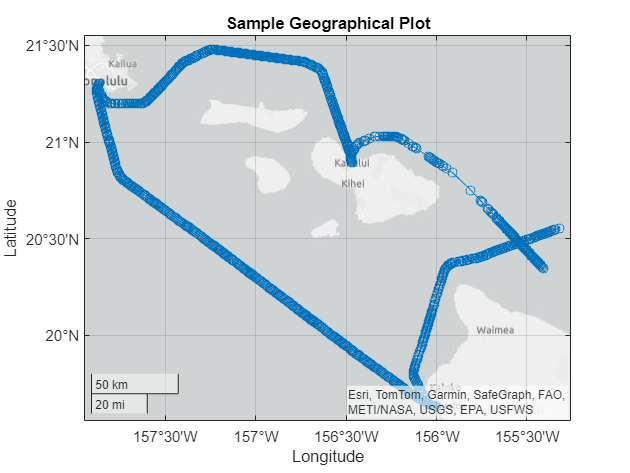

figure
% Create a geographical plot
geoplot(dataSubset.LAT, dataSubset.LON, 'o-')
title('Sample Geographical Plot')

% dataSubset=dataSubset(1:300,:);
[x,y,utmzone]=deg2utm(dataSubset.LAT, dataSubset.LON);
[o_Lat, o_Lon]=utm2deg(x,y,utmzone);
figure
% Create a geographical plot
geoplot(o_Lat, o_Lon, 'o-')
title('Sample Geographical Plot')

% Assuming temp is a table and BaseDateTime is a column in the 'dd/mm/yyyy HH:MM' format
dataSubset.BaseDateTime = datetime(dataSubset.BaseDateTime,'InputFormat','dd/MM/yyyy HH:mm');

% Convert datetime to seconds since epoch (Unix timestamp)
d = posixtime(dataSubset.BaseDateTime);

% Calculate time elapsed since the first timestamp
Tsec = d - d(1);
% Assuming 'Tsec' is your array of timestamps in seconds
diff_Tsec = diff(Tsec);

% Find the most common difference, which will be your sample time Ts
Ts = mode(diff_Tsec);

% state vector x=[LAT LON SOG HEADING]
state_vector=[x,y,dataSubset.SOG, deg2rad(dataSubset.Heading)];
state_vector=state_vector';

% Initialize the state history
x_hist = state_vector(:,1);
% Simulation loop
for index= 2:1:length(state_vector)
    w=rand(2,1);
    % Define the state transition matrix
;


    % Store the state history
    x_hist = [x_hist, x_dot];
end

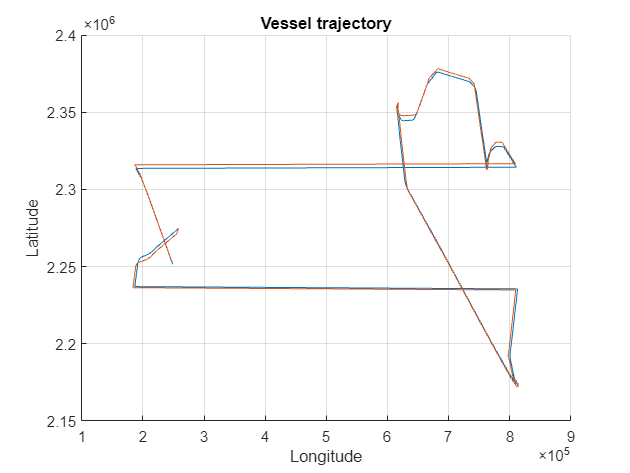


% Plot the latitude and longitude

figure
hold on
plot(x,y)
plot(x_hist(1,:), x_hist(2,:))
xlabel('Longitude')
ylabel('Latitude')
title('Vessel trajectory')
grid on

[m_Lat, m_Lon]=utm2deg(x_hist(1,:),x_hist(2,:),utmzone);


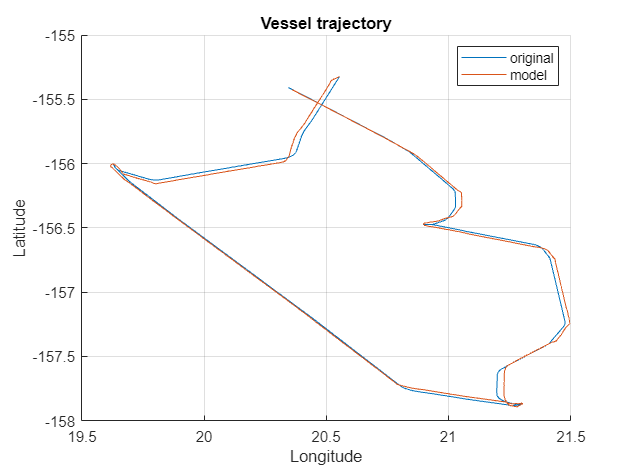


figure
hold on
plot(o_Lat, o_Lon)
plot(m_Lat, m_Lon)
xlabel('Longitude')
ylabel('Latitude')
title('Vessel trajectory')
legend('original','model')
grid on

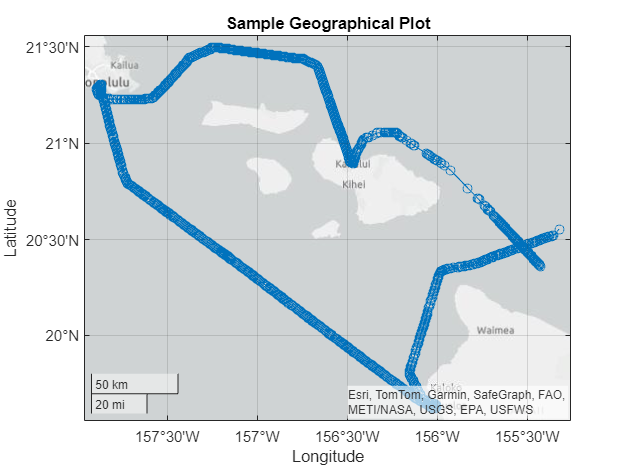

figure
% Create a geographical plot
geoplot(m_Lat, m_Lon, 'o-')
title('Sample Geographical Plot')

function x_k1 = state_transition(x_k, u_k, T_s)
    % State transition model
    x_k1 = F(x_k, T_s) * x_k + G(x_k) * u_k;
end

function w_k = process_noise(Q)
    % Process noise
    w_k = mvnrnd(zeros(size(Q,1),1), Q);
end

function e_k = measurement_noise(R)
    % Measurement noise
    e_k = mvnrnd(zeros(size(R,1),1), R);
end

function x_k1_k = complete_motion_model(x_k_k1, u_k, T_s, Q, R)
    % Equation (7)
    w_k = process_noise(Q);
    
    % Equation (8)
    x_k1_k = state_transition(x_k_k1, u_k, T_s) + w_k;
    
    % Equation (9)
    e_k = measurement_noise(R);
    y_k = h(x_A) + e_k; % h and x_A need to be defined
end

function y = wendland(r)
    % Wendland function
    y = (1 - r).^4 .* (35*r.^2 + 18*r.^3 + 3)/3;
end

function r = compute_r(x_k, xi)
    % Compute r
    r = norm(x_k - xi);
end

function g = basis_expansion(x_k, theta, A_0)
    % Basis expansion
    phi = wendland(compute_r(x_k, xi)); % xi needs to be defined
    g = phi' * A_0 * theta; % A_0 and theta need to be defined
end